This script will look at the determination of eddy center locations using several different algorithms, their subsequent use to determine the eddy-fixed reference frame or co-moving frame, and finally the determination of the largest instantaneous closed streamline or trapping region.  You'll need [BetaEddyOne](https://zenodo.org/records/8200056), [jLab](https://github.com/jonathanlilly/jLab), and the [Crameri colormaps](https://www.mathworks.com/matlabcentral/fileexchange/68546-crameri-perceptually-uniform-scientific-colormaps).

First we will load the data and compute the eddy center via several definitions.  

%This is when your NetCDF file is kept
ncdir='/Users/lilly/Desktop/Dropbox/NetCDF/';
filename='BetaEddyOne.nc';

%loading in data
lato=ncread([ncdir filename],'latitude');
f0=abs(corfreq(lato))/3600; %rad/s

x=ncread([ncdir filename],'x')/1000;%store distances in km
y=ncread([ncdir filename],'y')/1000;%store distances in km
ssh=squeeze(ncread([ncdir filename],'ssh'))*100;%store ssh in cm

%vorticity, shear strain, and normal strain, nondimensionalized by f0
zeta=squeeze(ncread([ncdir filename],'zeta'))/f0;
sigma=squeeze(ncread([ncdir filename],'sigma'))/f0;
nu=squeeze(ncread([ncdir filename],'nu'))/f0;
 
okubo=sigma.^2+nu.^2-zeta.^2; %okubo-weiss

clear xo yo xc yc
j=0;
% 1:  vorticity minimum itself  
j=j+1;[xo{j},yo{j},xc{j},yc{j}]=eddyCenterFromField(x,y,zeta,1.0,method="timesMin");
% 2: 0.9 times vorticity minimum
j=j+1;[xo{j},yo{j},xc{j},yc{j}]=eddyCenterFromField(x,y,zeta,0.9,method="timesMin");
% 3: ssh maximum itself
j=j+1;[xo{j},yo{j},xc{j},yc{j}]=eddyCenterFromField(x,y,ssh,1.0,method="timesMax");
% 4: 0.9 times ssh maximum 
j=j+1;[xo{j},yo{j},xc{j},yc{j}]=eddyCenterFromField(x,y,ssh,0.9,method="timesMax");
% 5: okubo-weiss minimum itself
j=j+1;[xo{j},yo{j},xc{j},yc{j}]=eddyCenterFromField(x,y,okubo,1.0,method="timesMin");
% 6: 0.9 times okubo-weiss minimum
j=j+1;[xo{j},yo{j},xc{j},yc{j}]=eddyCenterFromField(x,y,okubo,0.9,method="timesMin");
% 7: Zero vorticity contour containing vorticity minimum 
j=j+1;[xo{j},yo{j},xc{j},yc{j}]=eddyCenterFromField(x,y,zeta,0,contains = {xo{1},yo{1}});

Now we will plot these center locations over the first 100 days. The origin (0,0) is the original location of the eddy. 

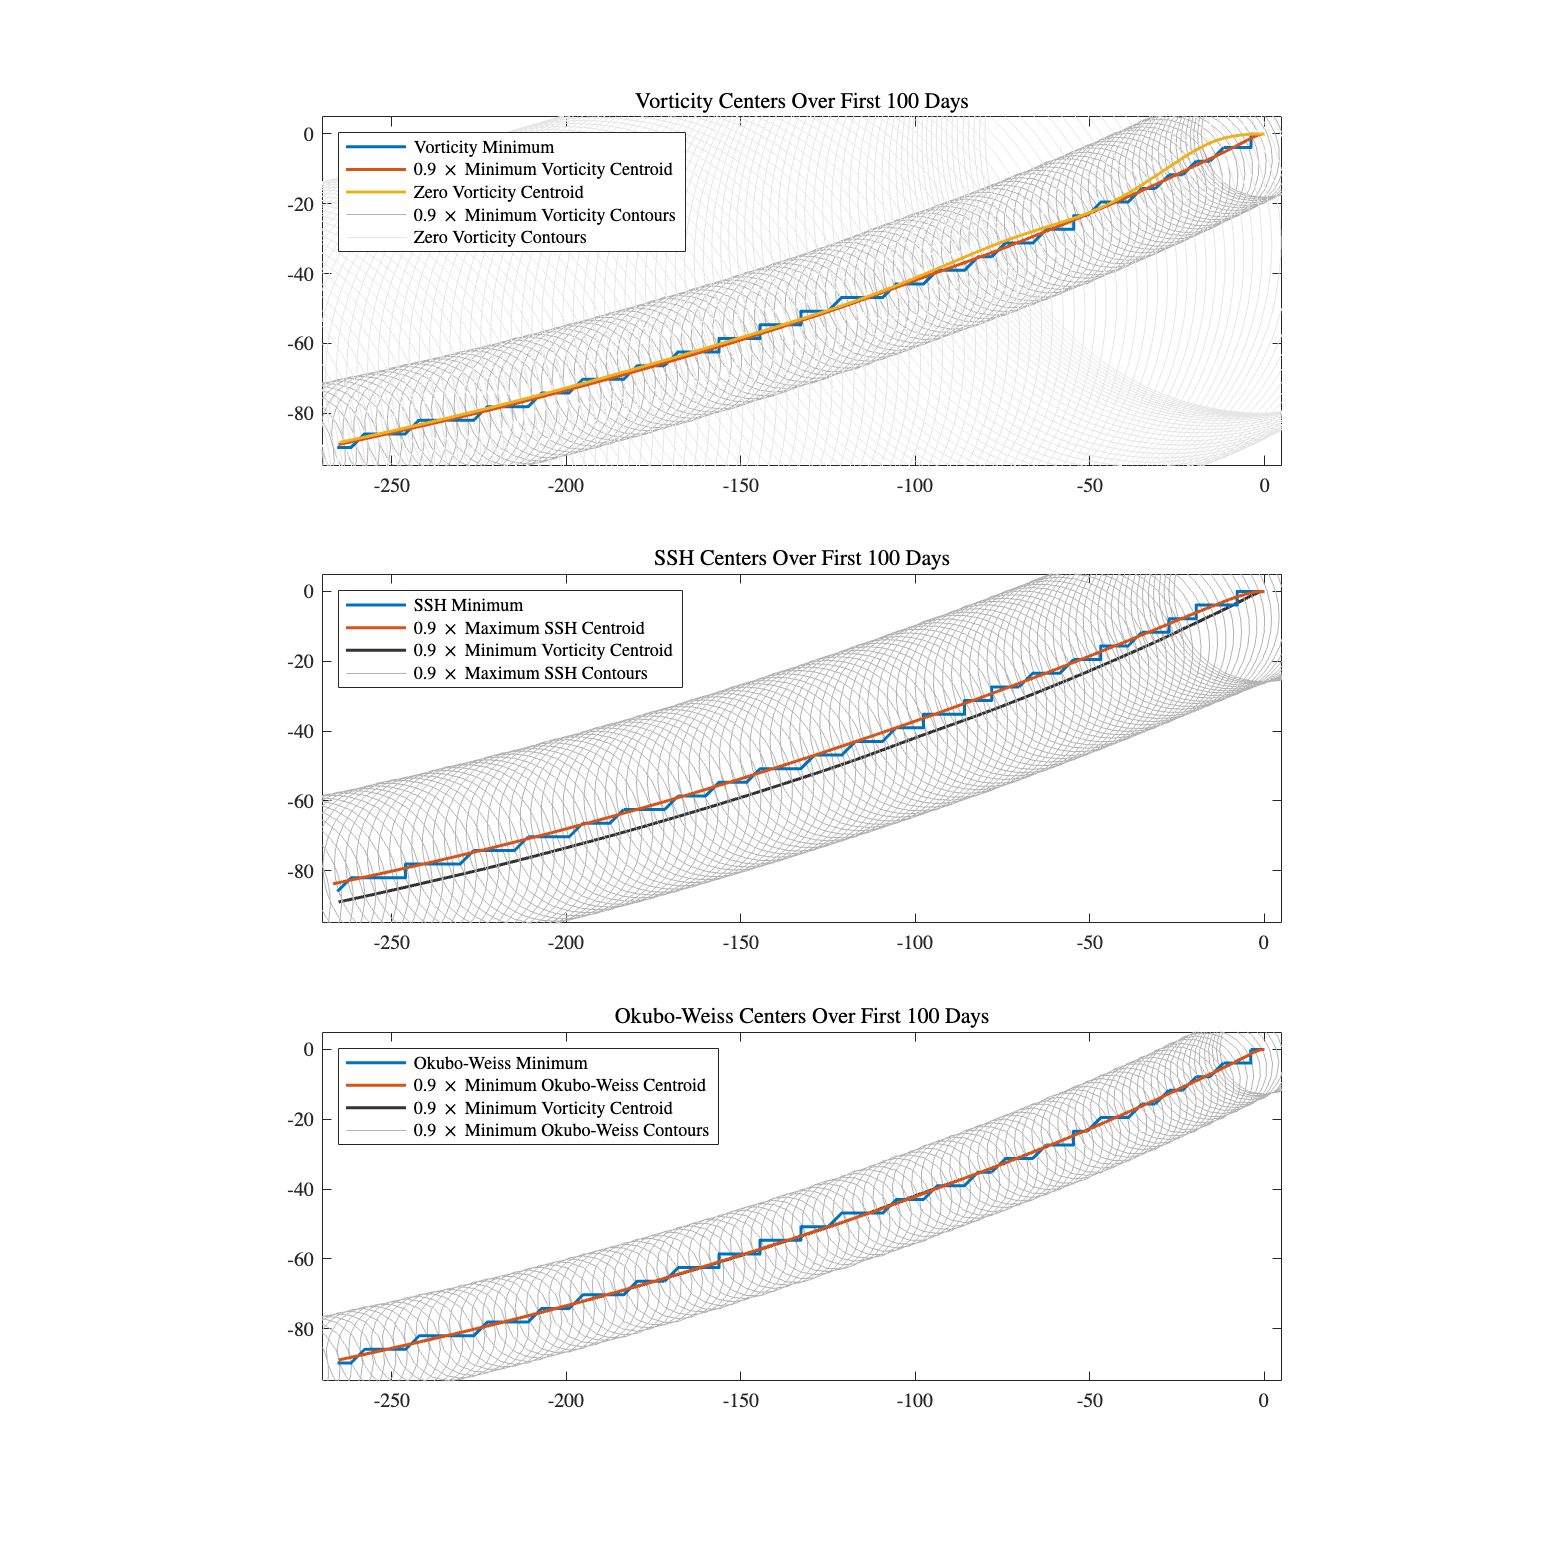

hf = figure();
hf.Position(3:4) = [1200, 1200];
ax=[-270 5 -95 5];
hl = gobjects(7,1);  %initialize a graphics array to store line handles. 

tiledlayout(3,1);
nexttile
for j=[1 2 7]
    hl(j) = plot(xo{j}(1:100)-xo{1}(1),yo{j}(1:100)-yo{1}(1),Zdata=5+zeros(100,1),linewidth=1.5);hold on,axis equal
end 
hlo1 = cellplot(celladd(xc{2},-xo{1}(1)),celladd(yc{2},-yo{1}(1)),'0.25D');hold on
hlo2 = cellplot(celladd(xc{7},-xo{1}(1)),celladd(yc{7},-yo{1}(1)),'0.25B');hold on
axis(ax)
title("Vorticity Centers Over First 100 Days")
legend([hl([1 2 7]);hlo1(1);hlo2(1)],'Vorticity Minimum','0.9 $\times$ Minimum Vorticity Centroid','Zero Vorticity Centroid','0.9 $\times$ Minimum Vorticity Contours','Zero Vorticity Contours',location="northwest")

nexttile
for j=[3 4 2]
    hl(j) = plot(xo{j}(1:100)-xo{1}(1),yo{j}(1:100)-yo{1}(1),Zdata=5+zeros(100,1),linewidth=1.5);hold on,axis equal,box on
end 
hl(2).Color = 0.2*[1 1 1];
hl(2).ZData = -1+0*hl(2).XData; %set vorticity line to be under other lines
hlo = cellplot(celladd(xc{4},-xo{1}(1)),celladd(yc{4},-yo{1}(1)),'0.25D');hold on

axis(ax)
title("SSH Centers Over First 100 Days")
legend([hl([3 4 2]);hlo(1)],'SSH Minimum','0.9 $\times$ Maximum SSH Centroid', '0.9 $\times$ Minimum Vorticity Centroid','0.9 $\times$ Maximum SSH Contours',location="northwest")

nexttile
for j=[5 6 2]
    hl(j) = plot(xo{j}(1:100)-xo{1}(1),yo{j}(1:100)-yo{1}(1),Zdata=5+zeros(100,1),linewidth=1.5);hold on,axis equal
end 
hl(2).Color = 0.2*[1 1 1];
hl(2).ZData = -1+0*hl(2).XData; %set vorticity line to be under other lines
hlo = cellplot(celladd(xc{6},-xo{1}(1)),celladd(yc{6},-yo{1}(1)),'0.25D');hold on

axis(ax)
title("Okubo-Weiss Centers Over First 100 Days")
legend([hl([5 6 2]);hlo(1)],'Okubo-Weiss Minimum','0.9 $\times$ Minimum Okubo-Weiss Centroid', '0.9 $\times$ Minimum Vorticity Centroid','0.9 $\times$ Minimum Okubo-Weiss Contours',location="northwest")

The take-aways are: (i) the 0.9 x vorticity minimum contour resembles a filtered versions of the jagged vorticity minimum location, but the zero-vorticity contour departs from this; (ii) SSH center is systematically shifted northward compared to the vorticity center; and (iii) the Okubo–Weiss center is indistiguishable from the vorticity center. 

Next, we will compare the implied eddy center velocities.  

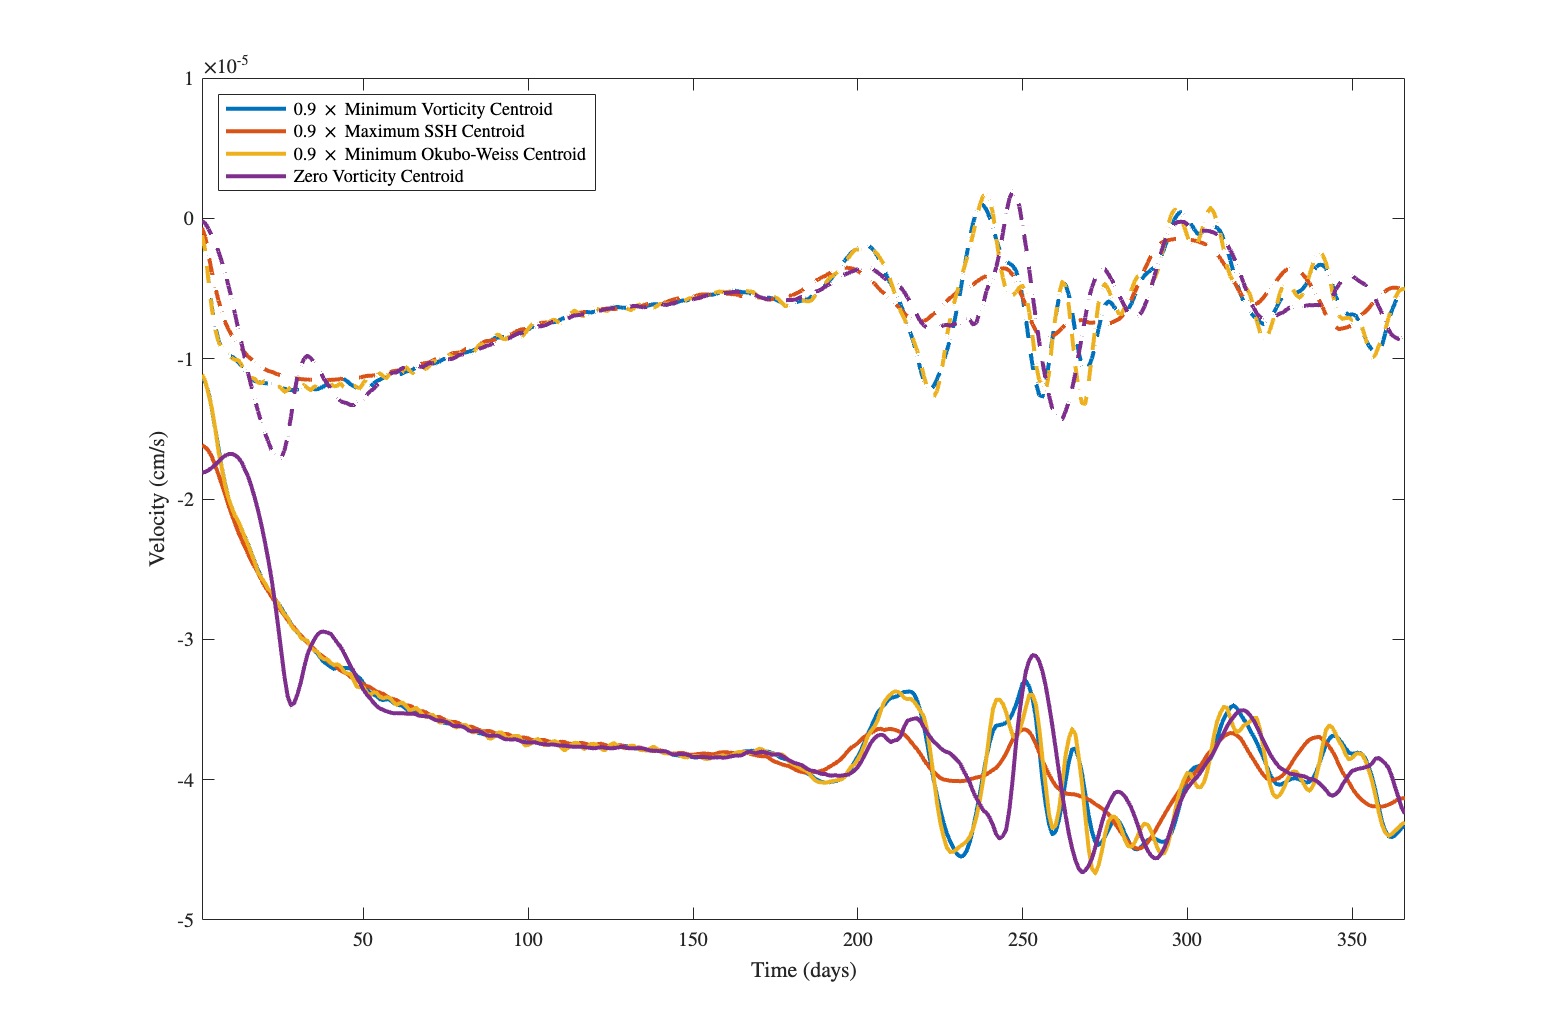

[u,v]=deal(zeros(size(ssh,3),7));
for j=1:length(xo)
    u(:,j)=vdiff(xo{j},1,'endpoint')/(24*3600); %convert m/day to cm/s
    v(:,j)=vdiff(yo{j},1,'endpoint')/(24*3600); %convert m/day to cm/s
end

hf = figure();
hf.Position(3:4) = [1200, 800];

hl1 = plot(1:size(u,1),u(:,[2 4 6 7]),linewidth=2); hold on
hl2 = plot(1:size(u,1),v(:,[2 4 6 7]),'--',linewidth=2);

%set v lines to same color as u lines 
for j=1:length(hl1)
    hl2(j).Color = hl1(j).Color;
end

legend('0.9 $\times$ Minimum Vorticity Centroid','0.9 $\times$ Maximum SSH Centroid','0.9 $\times$ Minimum Okubo-Weiss Centroid','Zero Vorticity Centroid',location="northwest")

xlim([1 366]),xlabel("Time (days)"),ylabel("Velocity (cm/s)")

Some take-aways: (i) zero vorticity centroid appears to have some extra low-frequency wiggles; (ii) Okubo–Weiss centroid appears to have some extra high-frequency jitter compared with vorticity minimum centroid; (iii) SSH minimum centroid has variability somewhat smaller in magnitude than that of vorticity minimum centroid.

Next we will interpolate the sea surface height into the eddy frame and examine it.

%first we do some computations 
[xo1,yo1]=eddyCenterFromField(x,y,ssh,0.9,method="timesMax");
[xo2,yo2]=eddyCenterFromField(x,y,zeta,0.9,method="timesMin");

[xp1,yp1,sshEddy1,zetaEddy1]=fieldInEddyFrame(x,y,xo1,yo1,300,ssh,zeta,dx=2.5);
[xp2,yp2,sshEddy2,zetaEddy2]=fieldInEddyFrame(x,y,xo2,yo2,300,ssh,zeta,dx=2.5);

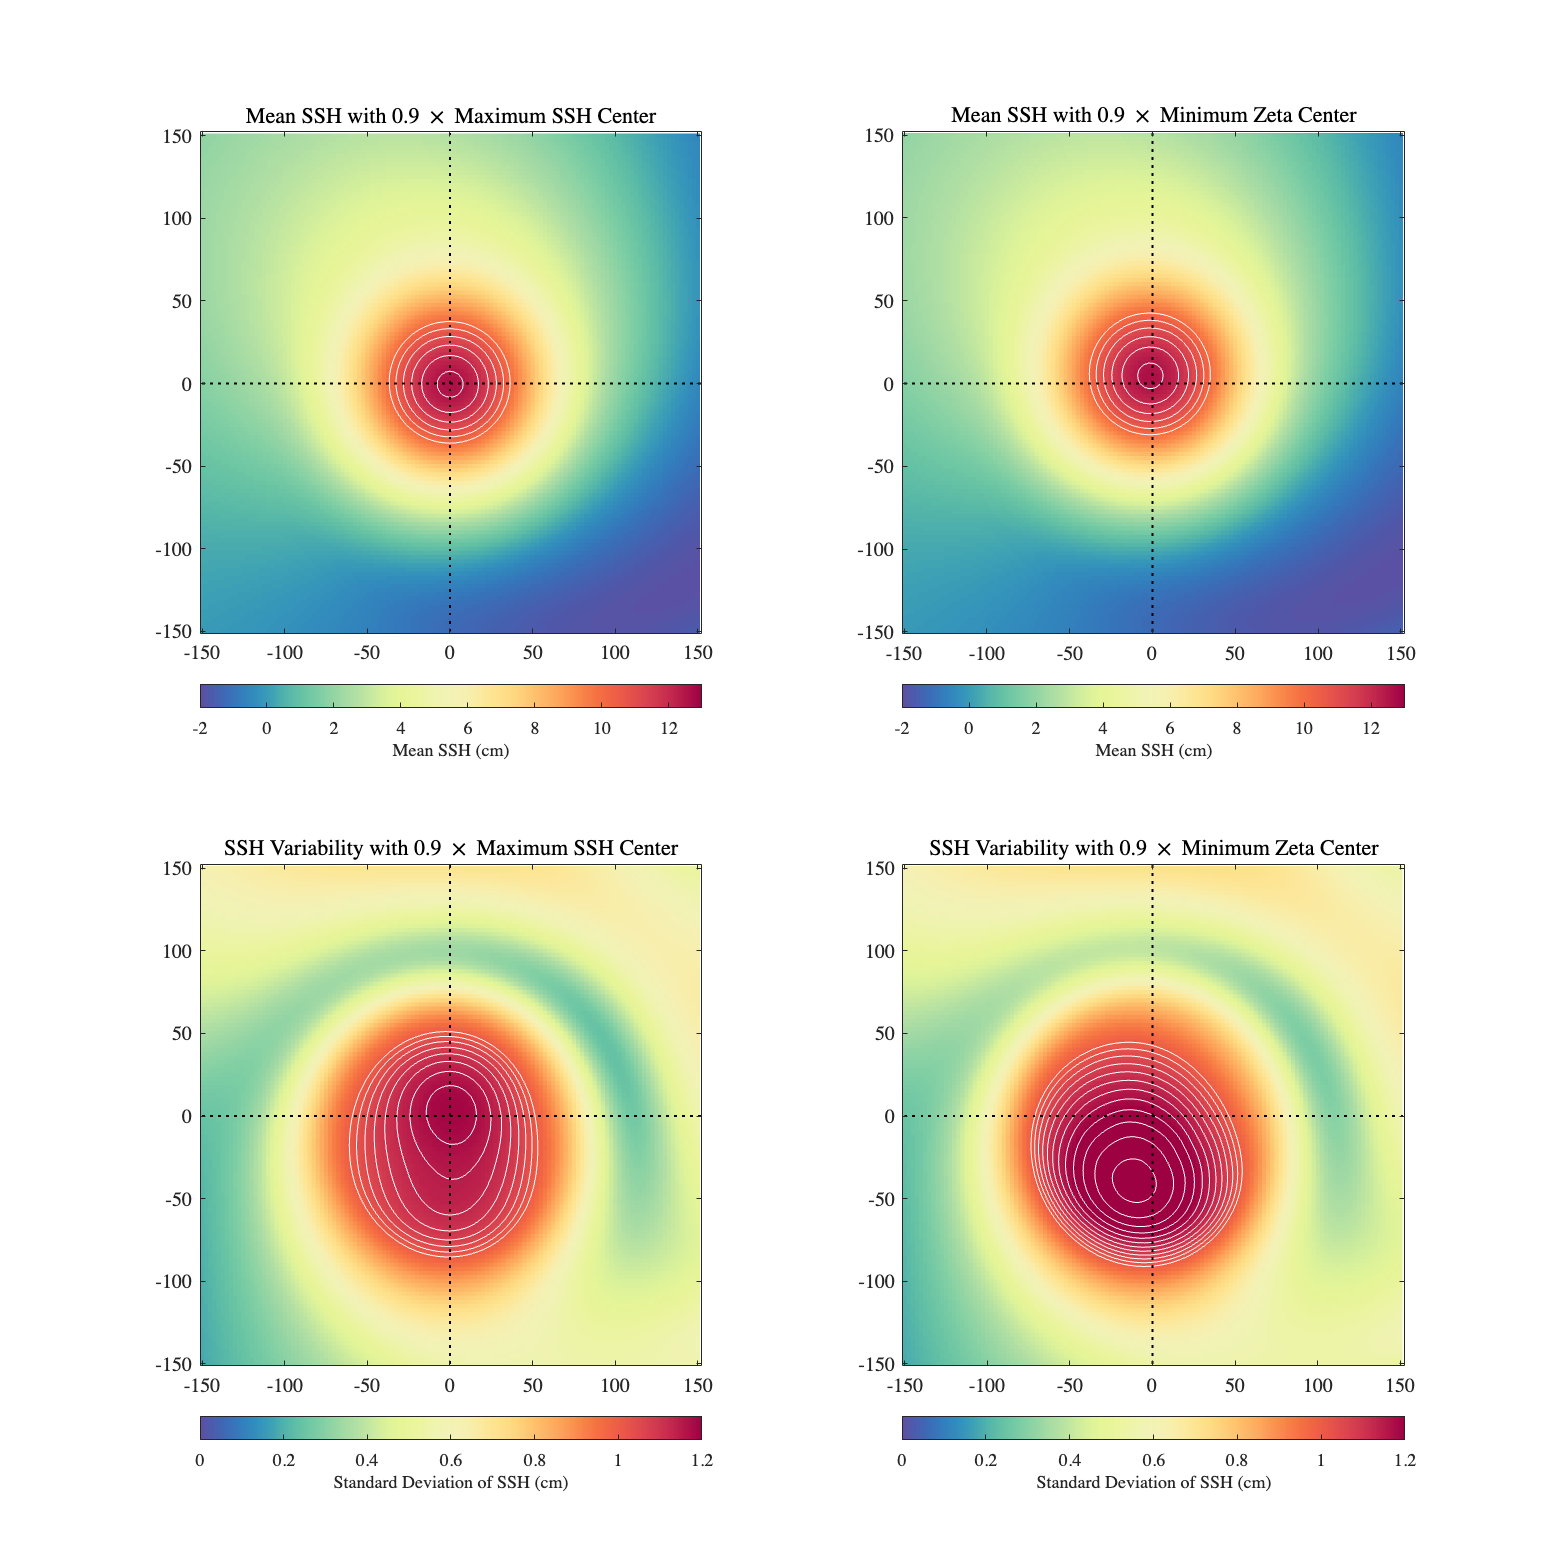

hf = figure();
hf.Position(3:4) = [1200, 1200];
tiledlayout(2,2);
colormap(lansey)

nexttile
%don't forget to transpose when using jpcolor or contour 
jpcolor(xp1,yp1,mean(sshEddy1,3)'),hc=colorbar('SouthOutside');
hc.Label.String = 'Mean SSH (cm)';clim([-.2 1.3]*10)
hold on,contour(xp1,yp1,mean(sshEddy1,3)',[1:.05:2]*10,'w')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('Mean SSH with 0.9 $\times$ Maximum SSH Center')

nexttile
jpcolor(xp2,yp2,mean(sshEddy2,3)'),hc=colorbar('SouthOutside');
hc.Label.String = 'Mean SSH (cm)';clim([-.2 1.3]*10)
hold on,contour(xp2,yp2,mean(sshEddy2,3)',[1:.05:2]*10,'w')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('Mean SSH with 0.9 $\times$ Minimum Zeta Center')

nexttile
jpcolor(xp1,yp1,std(sshEddy1,1,3)'),hc=colorbar('SouthOutside');
hc.Label.String = 'Standard Deviation of SSH (cm)';clim([0 1.2])
hold on,contour(xp1,yp1,std(sshEddy1,1,3)',[.1:.0025:.2]*10,'w')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('SSH Variability with 0.9 $\times$ Maximum SSH Center')

nexttile
jpcolor(xp2,yp2,std(sshEddy2,1,3)'),hc=colorbar('SouthOutside');
hc.Label.String = 'Standard Deviation of SSH (cm)';clim([0 1.2])
hold on,contour(xp2,yp2,std(sshEddy2,1,3)',[.1:.0025:.2]*10,'w')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('SSH Variability with 0.9 $\times$ Minimum Zeta Center')

We see that when using the SSH maximum to define the eddy center, the SSH standard deviation is also maximized at the eddy center.  When using the vorticity minimum to define the eddy center, the peak of the mean SSH field is shifted slightly northward, whereas the peak of the SSH standard deviation is shifted considerably southward. 

Let's do the same but examining vorticity. 

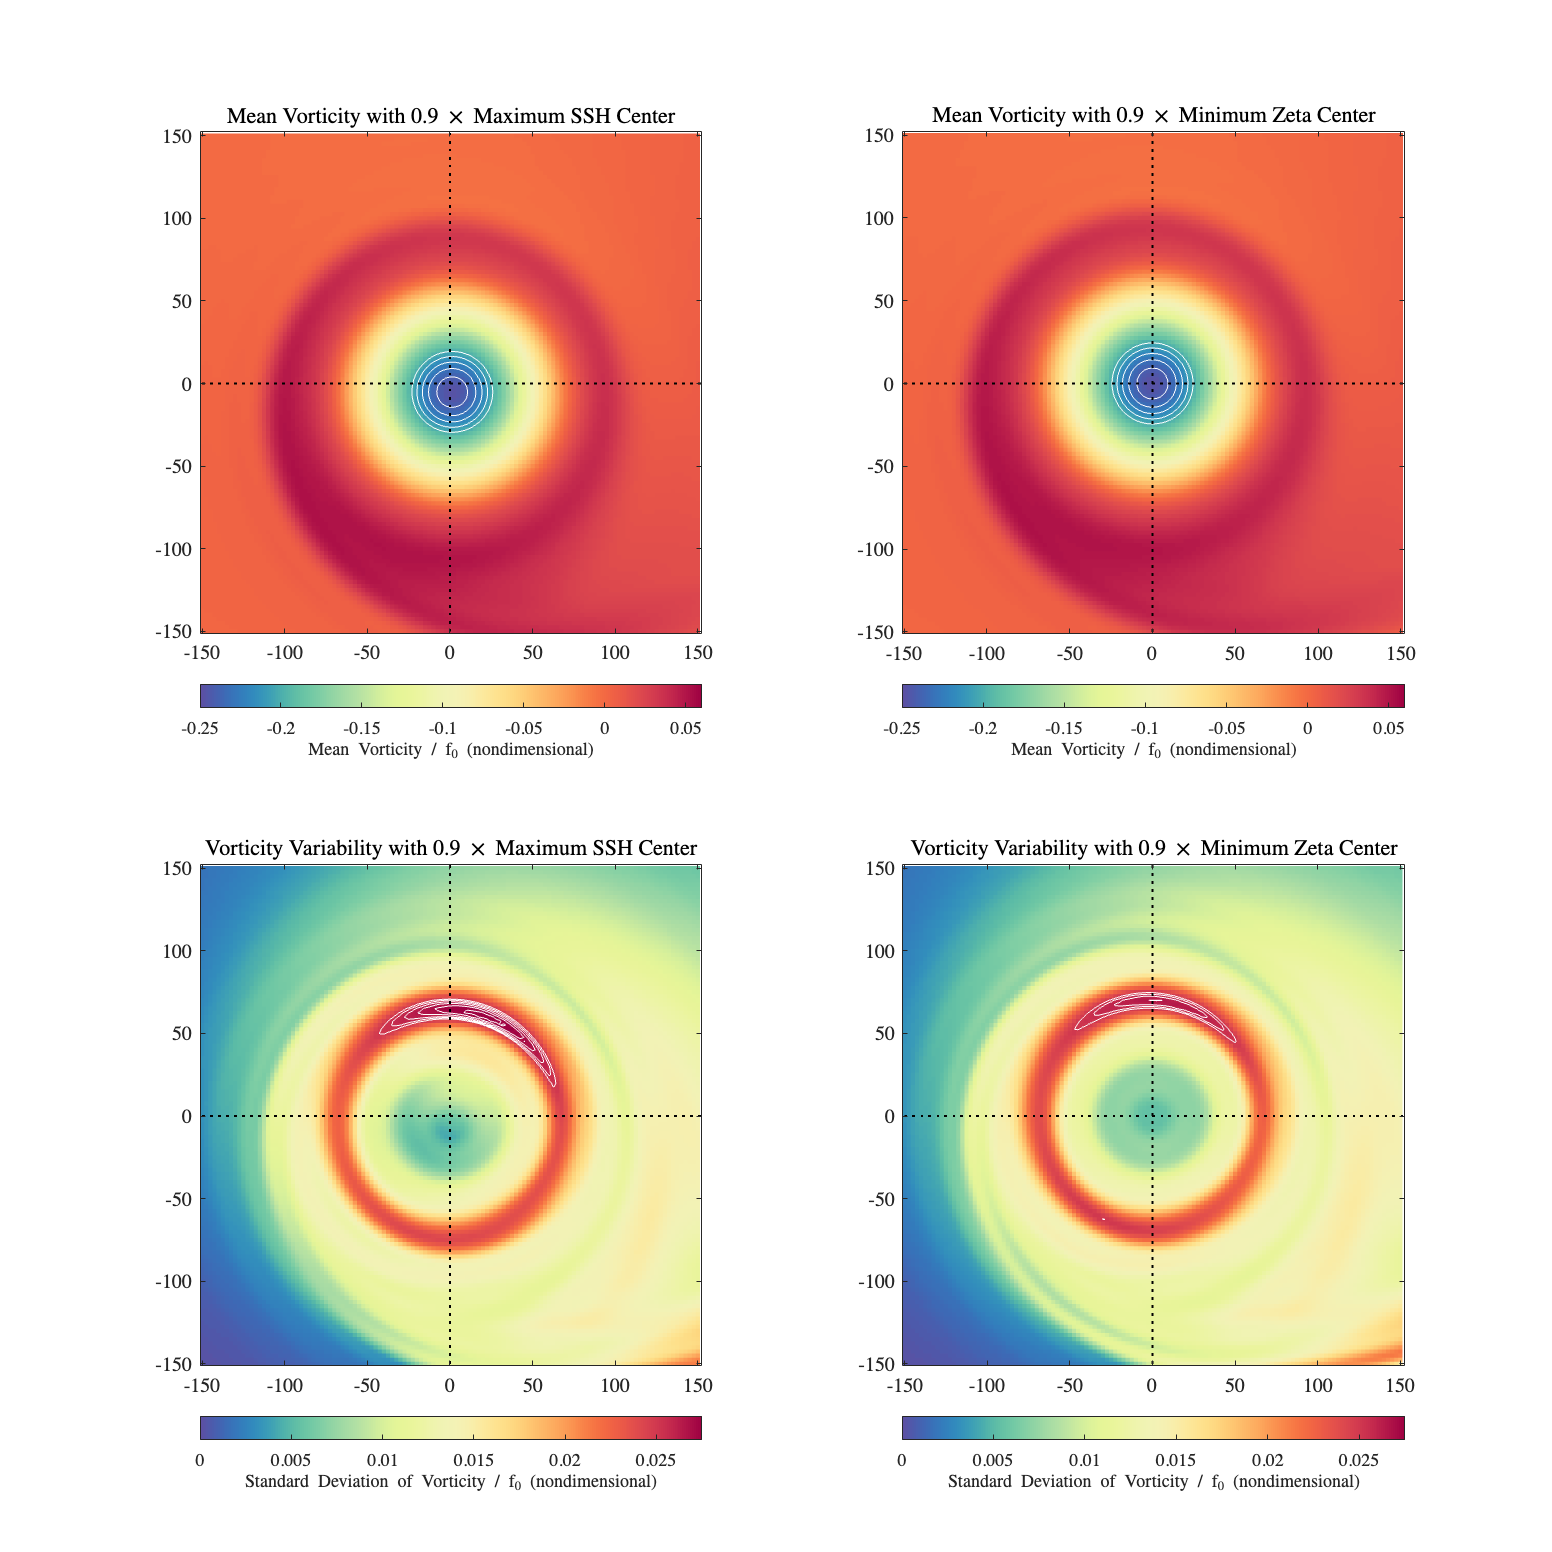

hf = figure();
hf.Position(3:4) = [1200, 1200];
tiledlayout(2,2);
colormap(lansey)

nexttile
jpcolor(xp1,yp1,mean(zetaEddy1,3)'),hc=colorbar('SouthOutside');
hc.Label.String = 'Mean Vorticity / f_0 (nondimensional)';clim([-.25 0.06])
hold on,contour(xp1,yp1,mean(zetaEddy1,3)',[-.3:.01:-.2],'w')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('Mean Vorticity with 0.9 $\times$ Maximum SSH Center')

nexttile
jpcolor(xp1,yp1,mean(zetaEddy2,3)'),hc=colorbar('SouthOutside');
hc.Label.String = 'Mean Vorticity / f_0 (nondimensional)';clim([-.25 0.06])
hold on,contour(xp1,yp1,mean(zetaEddy2,3)',[-.3:.01:-.2],'w')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('Mean Vorticity with 0.9 $\times$ Minimum Zeta Center')

nexttile
jpcolor(xp1,yp1,std(zetaEddy1,1,3)'),hc=colorbar('SouthOutside');
hc.Label.String = 'Standard Deviation of Vorticity / f_0 (nondimensional)';clim([0 .0275])
hold on,contour(xp1,yp1,std(zetaEddy1,1,3)',[.025:0.0005:.028],'w')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('Vorticity Variability with 0.9 $\times$ Maximum SSH Center')

nexttile
jpcolor(xp1,yp1,std(zetaEddy2,1,3)'),hc=colorbar('SouthOutside');
hc.Label.String = 'Standard Deviation of Vorticity / f_0 (nondimensional)';clim([0 .0275])
hold on,contour(xp1,yp1,std(zetaEddy2,1,3)',[.025:0.0005:.028],'w')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('Vorticity Variability with 0.9 $\times$ Minimum Zeta Center')

The mean vorticity peak is very shifted slightly southward using the SSH definition of the eddy center, and the vorticity standard deviation is slightly more enchanced to the eddy's north, but these patterns differ much less than as seen above for the SSH field. 

Next we will look at the streamfunctions for the eddy-relative flow, for the Earth-relative flow, and for the velocity of the eddy frame itself. 

[xo,yo]=eddyCenterFromField(x,y,ssh,0.9,method="timesMax");
[xp,yp,sshEddy,zetaEddy]=fieldInEddyFrame(x,y,xo,yo,300,ssh,zeta,dx=2.5);

uo=vdiff(xo,1,'endpoint')*100*1000/(24*3600);%km/day to cm/s
vo=vdiff(yo,1,'endpoint')*100*1000/(24*3600);%km/day to cm/s

[psip,psi,psif] = eddyFrameStreamFunction(1000*xp,1000*yp,sshEddy/100,uo/100,vo/100,f0);

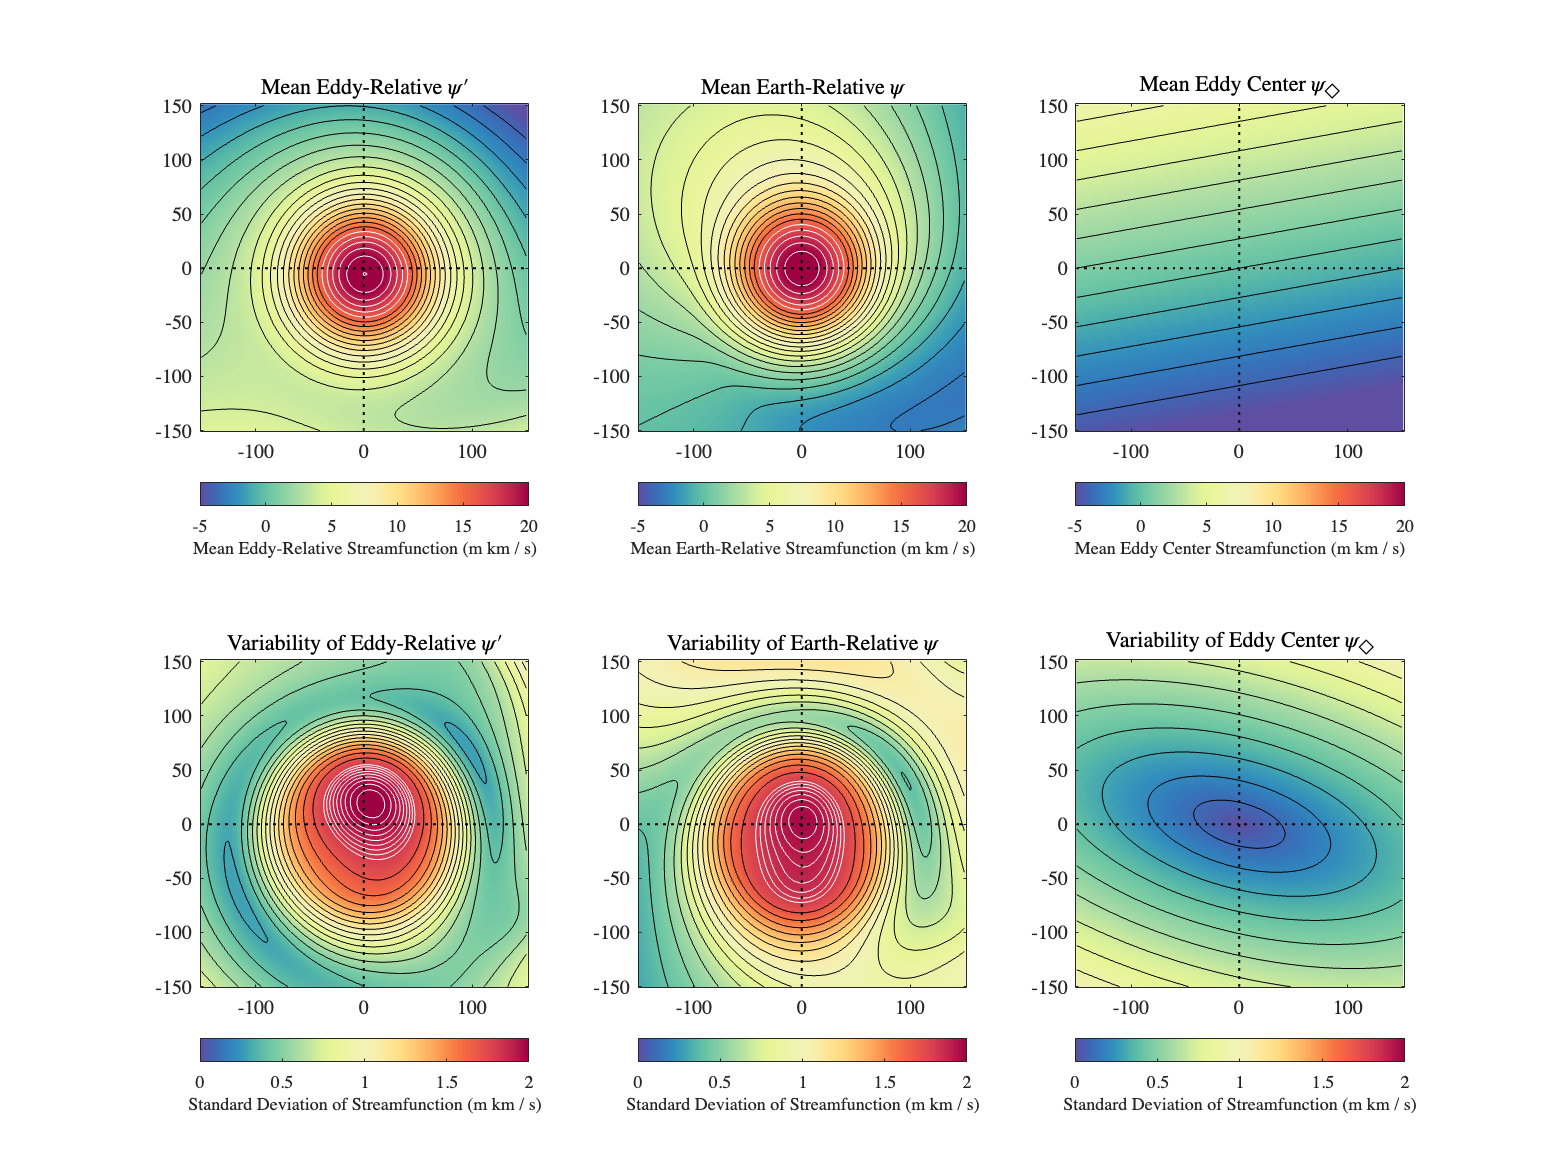

hf = figure();
hf.Position(3:4) = [1600, 1200];
tiledlayout(2,3);
colormap(lansey)

nexttile
jpcolor(xp,yp,mean(psip,3)'/1000),hc=colorbar('SouthOutside');
hc.Label.String = 'Mean Eddy-Relative Streamfunction (m km / s)';clim([-5 20])
hold on,contour(xp,yp,mean(psip,3)'/1000,[15:1:22],'w')
hold on,contour(xp,yp,mean(psip,3)'/1000,[-4:1:15],'k')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('Mean Eddy-Relative $\psi\prime$')

nexttile
jpcolor(xp,yp,mean(psi,3)'/1000),hc=colorbar('SouthOutside');
hc.Label.String = 'Mean Earth-Relative Streamfunction (m km / s)';clim([-5 20])
hold on,contour(xp,yp,mean(psi,3)'/1000,[15:1:22],'w')
hold on,contour(xp,yp,mean(psi,3)'/1000,[-4:1:15],'k')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('Mean Earth-Relative $\psi$')

nexttile
jpcolor(xp,yp,mean(psif,3)'/1000),hc=colorbar('SouthOutside');
hc.Label.String = 'Mean Eddy Center Streamfunction (m km / s)';clim([-5 20])
hold on,contour(xp,yp,mean(psif,3)'/1000,[15:1:22],'w')
hold on,contour(xp,yp,mean(psif,3)'/1000,[-4:1:15],'k')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('Mean Eddy Center $\psi_\diamond$')

nexttile
jpcolor(xp,yp,std(psip,1,3)'/1000),hc=colorbar('SouthOutside');
hc.Label.String = 'Standard Deviation of Streamfunction (m km / s)';clim([0 2])
hold on,contour(xp,yp,std(psip,1,3)'/1000,[0:.1:1.7],'k')
hold on,contour(xp,yp,std(psip,1,3)'/1000,[1.8:.025:2],'w')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('Variability of Eddy-Relative $\psi\prime$')

nexttile
jpcolor(xp,yp,std(psi,1,3)'/1000),hc=colorbar('SouthOutside');
hc.Label.String = 'Standard Deviation of Streamfunction (m km / s)';clim([0 2])
hold on,contour(xp,yp,std(psi,1,3)'/1000,[0:.1:1.7],'k')
hold on,contour(xp,yp,std(psi,1,3)'/1000,[1.8:.025:2],'w')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('Variability of Earth-Relative $\psi$')

nexttile
jpcolor(xp,yp,std(psif,1,3)'/1000),hc=colorbar('SouthOutside');
hc.Label.String = 'Standard Deviation of Streamfunction (m km / s)';clim([0 2])
hold on,contour(xp,yp,std(psif,1,3)'/1000,[0:.1:1.7],'k')
hold on,contour(xp,yp,std(psif,1,3)'/1000,[1.8:.025:2],'w')
vlines(0,'k:'),hlines(0,'k:'),axis equal,axis tight
title('Variability of Eddy Center $\psi_\diamond$')

We see that the streamfunction for the eddy-rleative flow is more azimuthally symmetric than the streamfunction for the Earth-relative flow, with smaller variabiilty around its time mean at each spatial location within the moving eddy frame.  

Next we will find the largest instantaneous closed streamlines of the eddy-relative and Earth-relative flow. 

[xo,yo]=eddyCenterFromField(x,y,ssh,0.9,method="timesMax");
[xp,yp,sshEddy,zetaEddy]=fieldInEddyFrame(x,y,xo,yo,300,ssh,zeta,dx=2.5);

uo=vdiff(xo,1,'endpoint')*100*1000/(24*3600);%km/day to cm/s
vo=vdiff(yo,1,'endpoint')*100*1000/(24*3600);%km/day to cm/s

[psip,psi,psif] = eddyFrameStreamFunction(1000*xp,1000*yp,sshEddy/100,uo/100,vo/100,f0);

tic;
[xpc,ypc,levels,index]=largestClosedStreamLine(xp,yp,psip/1000,0.25);
toc

Elapsed time is 18.025603 seconds.


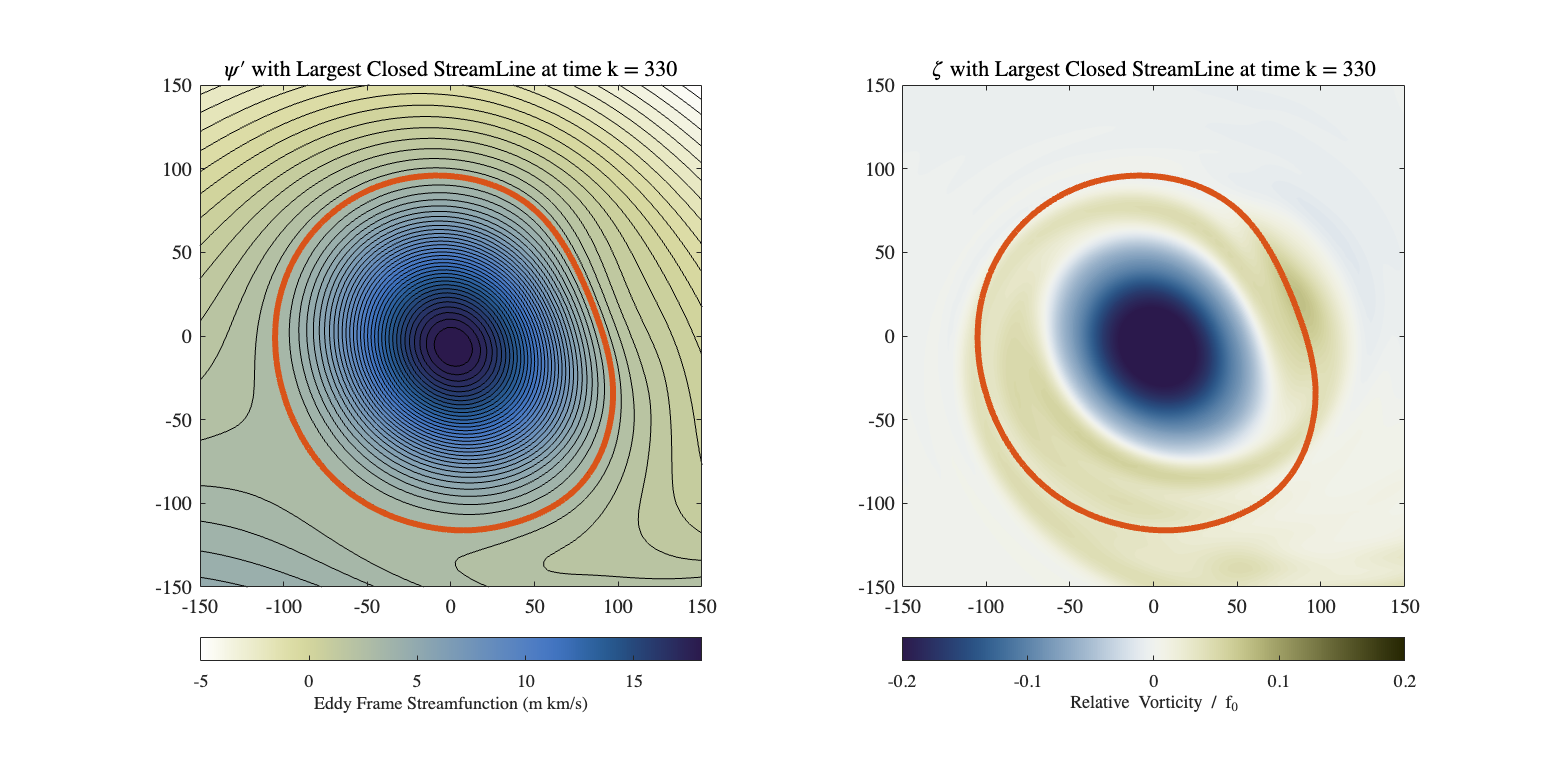

hf = figure();
hf.Position(3:4) = [1600,800];
k=330;

tiledlayout(1,2);

ax1=nexttile;
contourf(xp,yp,psip(:,:,k)'/1000,50),nocontours, hold on, axis equal
contour(xp,yp,psip(:,:,k)'/1000,50,'k')
cellplot(xpc(k),ypc(k),'3U')
hc=colorbar('location','SouthOutside');
hc.Label.String = "Eddy Frame Streamfunction (m km/s)";
title(['$\psi\prime$ with Largest Closed StreamLine at time k = ' int2str(k)])
colormap(ax1,flipud(crameri('davos')))

ax2=nexttile;
contourf(xp,yp,zetaEddy(:,:,k)',100),nocontours, hold on, axis equal
cellplot(xpc(k),ypc(k),'3U')
hc=colorbar('location','SouthOutside');
hc.Label.String = "Relative Vorticity / f_0";
clim([-.2 .2])
title(['$\zeta$ with Largest Closed StreamLine at time k = ' int2str(k)])
colormap(ax2,crameri('broc'))

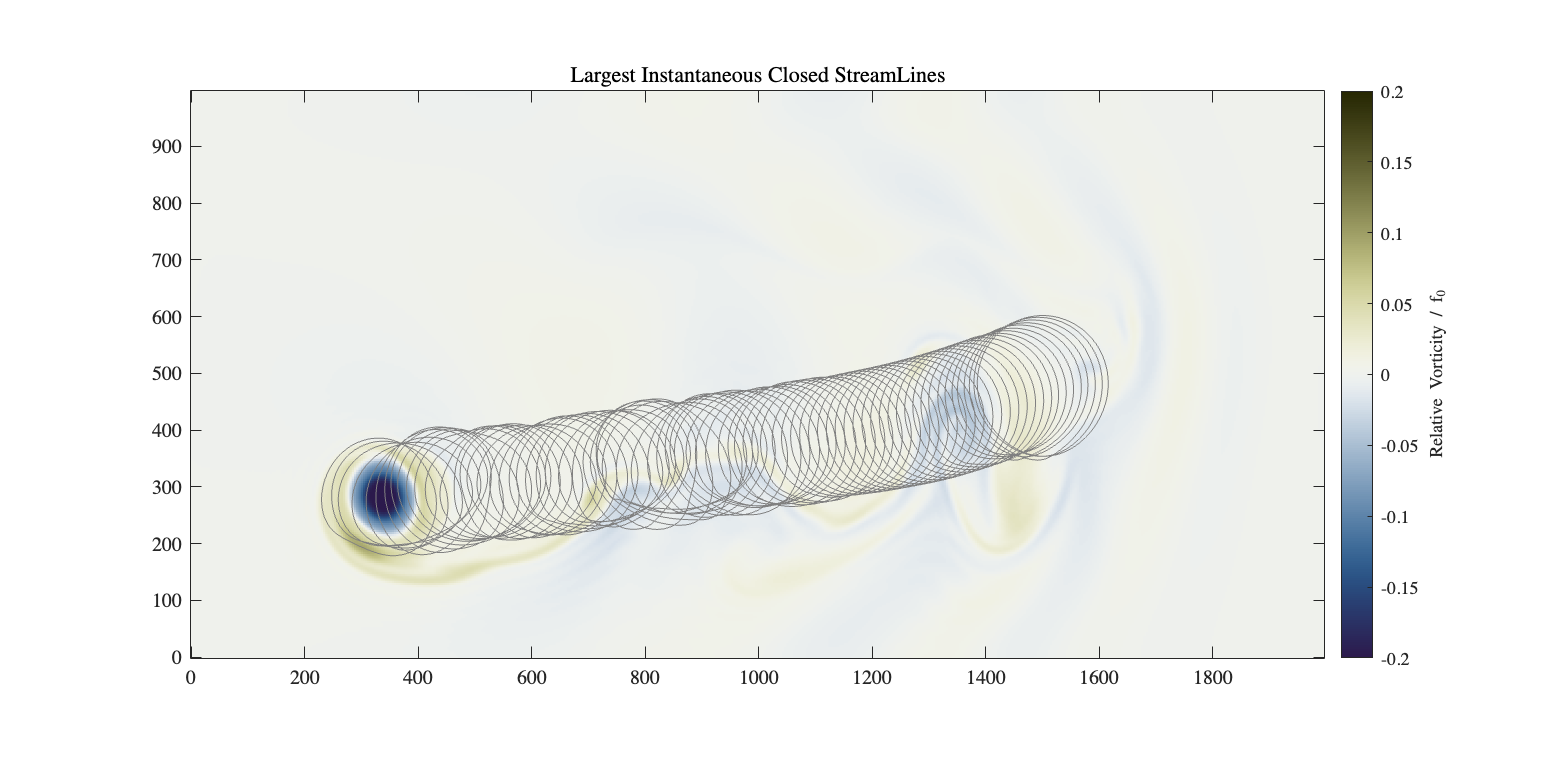

hf = figure();
hf.Position(3:4) = [1600, 800];
colormap(crameri('broc'));

jpcolor(x,y,zeta(:,:,end)'),hold on,axis equal,axis tight
%ii=1:5:length(xo);
%cellplot(celladd(xpc(ii),xo(ii)),celladd(ypc(ii),yo(ii)),'0.5F')
title("Largest Instantaneous Closed StreamLines")
clim([-.2 .2])
hc=colorbar('location','EastOutside');
hc.Label.String = "Relative Vorticity / f_0";

That's the end of this LiveScript.  Next, in EddyTransport, we will look at transport patterns, using the largest instantaneous closed streamline and other tools developed here.  